clear, clc, format short g


## PARTE 1

## 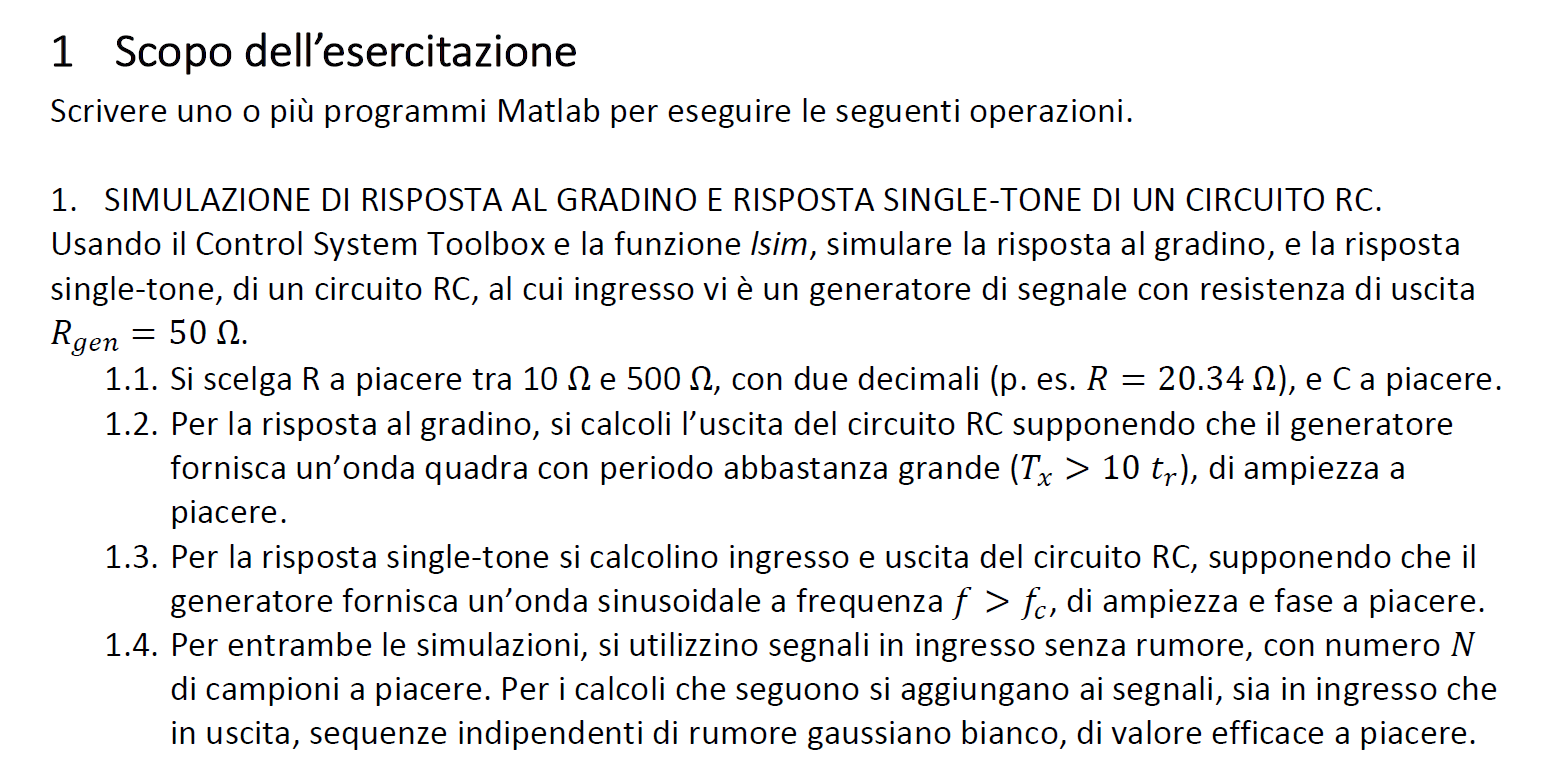


Rgen = 50;
R = 74.38;
C = 15e-9;

## definizione tau


tau_step = (R+Rgen)*C;
tau_sin = R*C

tau_sin =    1.1157e-06


## definizione periodi di campionamento

tr = tau_step*log(9)

tr =    4.0994e-06



Tx = 11*tr % durata periodo dell'onda quadra

Tx =    4.5093e-05


Np = 3; % numero di periodi simulati 

Td = Np*Tx % durata della simulazione

Td =    0.00013528



N = 1000;
n = (0:N-1)' %indici di campionamento

n =      0
     1
     2
     3
     4
     5
     6
     7
     8
     9



Ts = Td/N %periodo di campionamento

Ts =    1.3528e-07


t = n*Ts % istanti di campionamento

t =             0
   1.3528e-07
   2.7056e-07
   4.0584e-07
   5.4112e-07
   6.7639e-07
   8.1167e-07
   9.4695e-07
   1.0822e-06
   1.2175e-06


## definizione onda quadra in ingresso

Vpp = 10;

x_step = (Vpp/2)*square(2*pi*t/Tx)

x_step =      5
     5
     5
     5
     5
     5
     5
     5
     5
     5


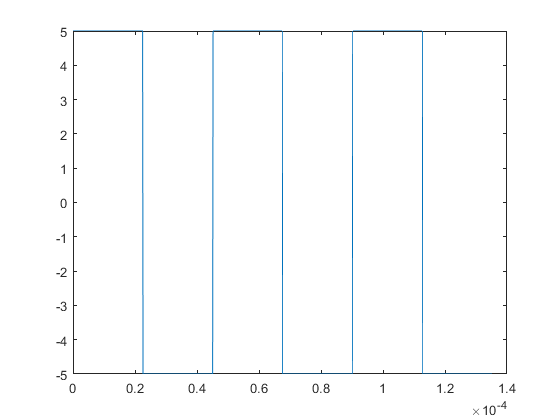


plot(t, x_step)

## definizione fdt

s = tf('s');

H1_dot = 1/(1+tau_step*s)


H1_dot =
 
         1
  ---------------
  1.866e-06 s + 1
 
Continuous-time transfer function.



## definizione risposta gradino

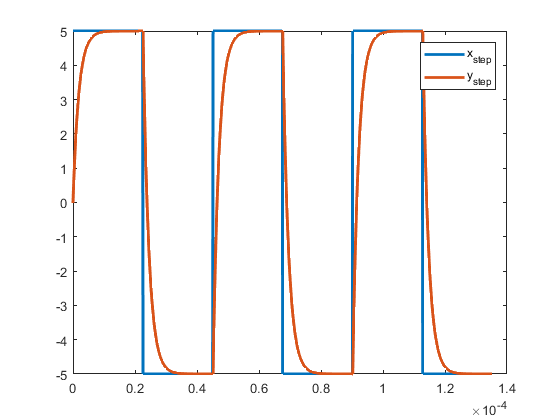

y_step = lsim(H1_dot, x_step, t);

plot(t, x_step, t, y_step, 'linewidth', 2)

legend('x_{step}', 'y_{step}')

## definizione parametri sinusoide

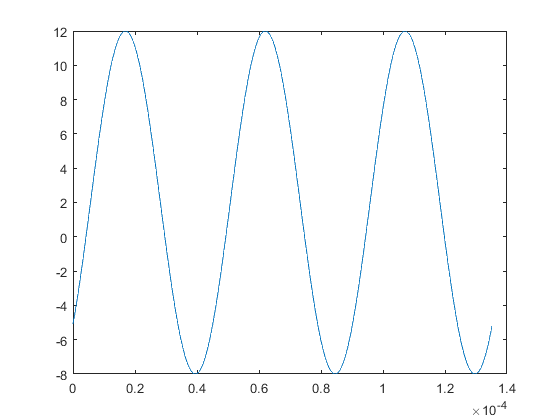

Np = 3;

Tx = Td/Np; % Durata simulazione rispetto al numero di periodi che ci interessa

fx = 1/Tx;

x_sin = 2 + Vpp*sin(2*pi*fx*t - pi/4);

plot(t, x_sin)

## definizione fdt

H_dot = 1/(1+tau_sin*s);


## definizione risposta seno

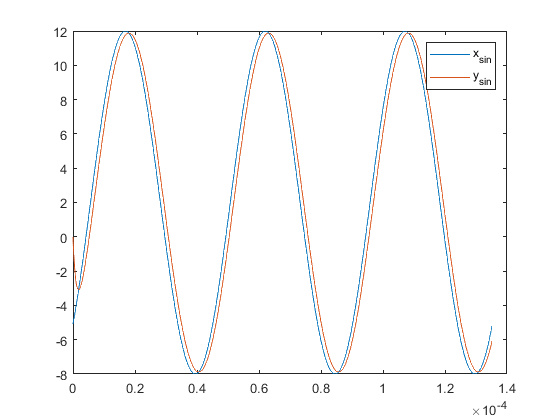

y_sin = lsim(H_dot, x_sin, t);

plot(t, x_sin, t, y_sin)

legend('x_{sin}', 'y_{sin}')

## 1.4

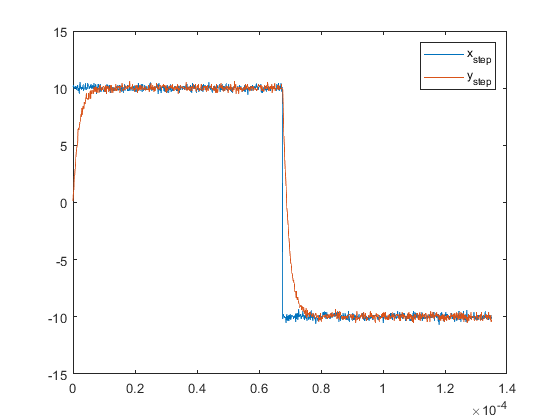

sigma = 0.2; %ampiezza del rumore
x_step = Vpp*square(2*pi*t/Td) + randn(N,1)*sigma; % segnale in ingresso con rumore AWGN

y_step = lsim(H1_dot, x_step, t) + randn(N,1)*sigma; % segnale in uscita con rumore AWGN indipendente dall'ingresso

plot(t,x_step, t, y_step)

legend('x_{step}', 'y_{step}')

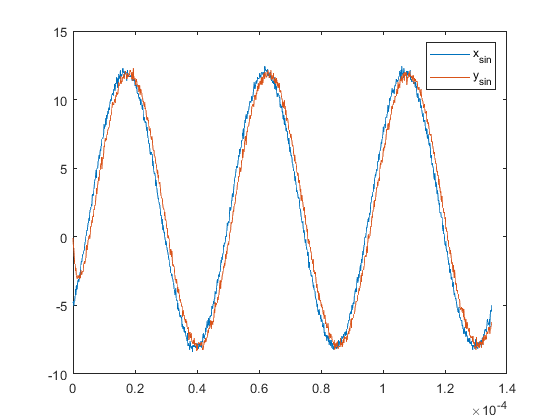


x_sin = 2 + Vpp*sin(2*pi*fx*t - pi/4) + randn(N,1)*sigma;
y_sin = lsim(H_dot, x_sin, t) + randn(N,1)*sigma;

plot(t,x_sin, t, y_sin)
legend('x_{sin}', 'y_{sin}')

## PARTE 2

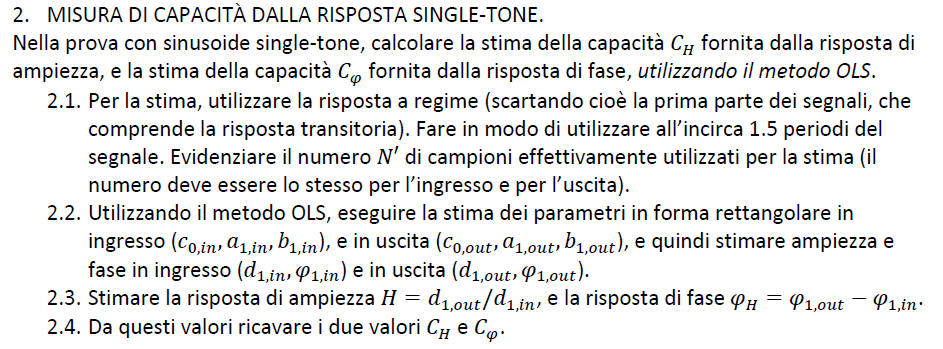

N2 = length(t)/2 % numero di campioni della risposta a regime

N2 =    500



t1 = (N2+1:N)' %vettore dei tempi contenenti gli istanti a regime

t1 =    501
   502
   503
   504
   505
   506
   507
   508
   509
   510


rng('default') % resetto il motore random

Fx = Np/N; %frequenza digitale
n = (0:N-1)'; %indici dei campioni

x_sin = 2 + Vpp*cos(2*pi*n*Fx - pi/4 - pi/2) + randn(N,1)*sigma; %trasformo seni in coseni per poter successivamente applicare il metodo OLS lineare
y_sin = lsim(H_dot, x_sin, t) + randn(N,1)*sigma;


xs = x_sin(N2+1:N) %segnale in ingresso ristretto agli ultimi campioni

xs =        9.0551
       9.1162
       8.8363
       8.7183
       8.5409
       8.4622
       8.2482
       8.6368
       7.6952
       7.4049


ys = y_sin(N2+1:N) %segnale in uscita ristretto agli ultimi campioni

ys =        9.6592
       9.9749
       9.8877
       9.6885
       9.5842
        9.327
       9.4539
       9.0408
       8.9311
       9.0592


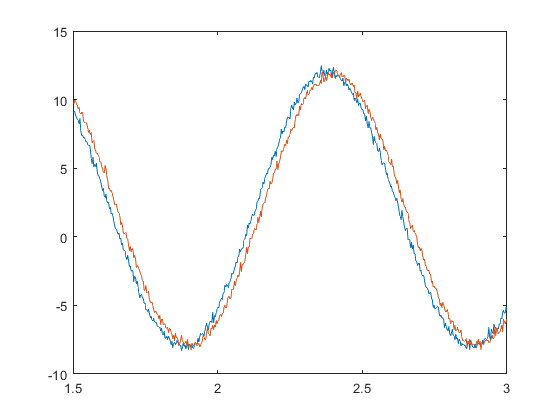



plot(t1*Fx, xs, t1*Fx, ys)


a1 = Vpp*cos(-3*pi/4); % coefficienti rettangolari
b1 = Vpp*sin(-3*pi/4);

wt = 2*pi*Fx*t1; % argomento delle funzioni base


A = [ones(N2,1), cos(wt), -sin(wt)]; % matrice delle funzioni base



## Stima dei parametri di y


theta_hat_y = (A'*A)^(-1)*A'*ys; % forma alternativa A\y

%estrazione della stima dei coefficienti della forma rettangolare in uscita
c0_hat_y = theta_hat_y(1)

c0_hat_y =          1.99


a1_hat_y= theta_hat_y(2)

a1_hat_y =       -8.0601


b1_hat_y = theta_hat_y(3)

b1_hat_y =       -5.6643



%stima dei coefficienti della forma polare in uscita

d1_hat_y = sqrt(a1_hat_y^2 + b1_hat_y^2)

d1_hat_y =        9.8513



phi1_hat_y = atan2(b1_hat_y, a1_hat_y)

phi1_hat_y =        -2.529


## Stima dei parametri di x

theta_hat_x = (A'*A)^(-1)*A'*xs;

theta_hat_x =        1.9871
      -7.1883
      -6.9166


 %% A\y

%estrazione della stima dei coefficienti della forma rettangolare in
%ingresso

c0_hat_x = theta_hat_x(1)

c0_hat_x =        1.9871


a1_hat_x = theta_hat_x(2)

a1_hat_x =       -7.1883


b1_hat_x = theta_hat_x(3)

b1_hat_x =       -6.9166



%stima dei coefficienti della forma polare in ingresso

d1_hat_x = sqrt(a1_hat_x^2 + b1_hat_x^2)

d1_hat_x =        9.9755



phi1_hat_x = atan2(b1_hat_x, a1_hat_x)

phi1_hat_x =       -2.3755


## Stima risposta di ampiezza e di fase

H = d1_hat_y/d1_hat_x

H =       0.98755



phi = phi1_hat_y - phi1_hat_x

phi =      -0.15356


## Ricavo C_H e C_phi


C_H = (sqrt(1-(H^2)/H)*(1/(2*pi*fx*R)))

C_H =    1.0765e-08



C_phi = tan(-phi)*(1/(2*pi*fx*R))

C_phi =    1.4934e-08


## Parte 3

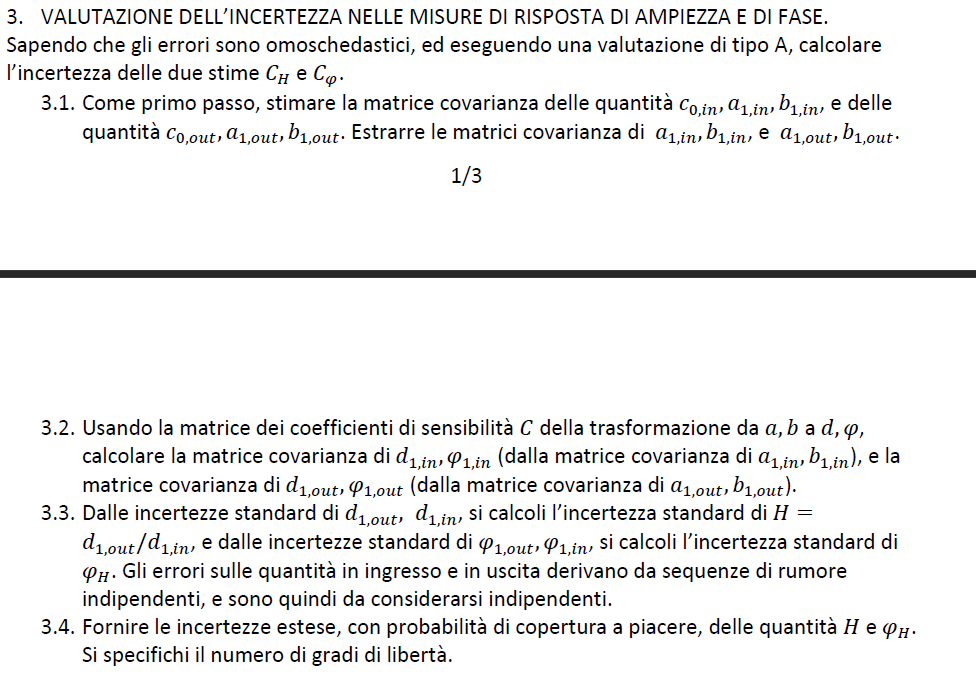

## stima con incertezza di tipo A

x_hat = A*theta_hat_x;

% stima dell'errore in ingresso
e_hat_x = ys - x_hat

e_hat_x =       0.61548
       1.0653
       1.1147
       1.0545
       1.0916
      0.97808
        1.251
        0.986
       1.0266
       1.3072



N_theta_x = length(theta_hat_x)

N_theta_x =      3



% Numero di gradi di libertà
nu = N-N_theta_x

nu =    997



% Stima varianzqa in ingresso con incertezza di tipo A
sigma2_x = sum(e_hat_x.^2)/nu

sigma2_x =       0.60523


## Stima matrice covarianza in ingresso sapendo che gli errori sono omoschedastici


sigma_theta_x = sigma2_x*(A'*A)^(-1)

sigma_theta_x =     0.0013303  -5.3211e-06  -0.00056457
  -5.3211e-06    0.0024209   2.2583e-06
  -0.00056457   2.2583e-06    0.0026605



% Estrazione della matrice covarianza in ingresso riferita ai due coefficienti della
% forma rettangolare indicati
sigma_theta_x_a1_b1 = sigma_theta_x(2:end, 2:end)

sigma_theta_x_a1_b1 =     0.0024209   2.2583e-06
   2.2583e-06    0.0026605


## stima con incertezza di tipo A della matrice covarianza in uscita

y_hat = A*theta_hat_y;

% stima errore in uscita
e_hat_y = ys - y_hat

e_hat_y =      -0.28269
      0.14401
      0.17061
     0.087954
      0.10294
    -0.032407
      0.21906
    -0.066958
    -0.046992
      0.21325



N_theta_y = length(theta_hat_y)

N_theta_y =      3



% gradi di libertà in uscita
nu = N-N_theta_y

nu =    997



% stima varianza in uscita
sigma2_y = sum(e_hat_y.^2)/nu

sigma2_y =      0.020636



% stima matrice covarianza in uscita
sigma_theta_y = sigma2_y*(A'*A)^(-1)

sigma_theta_y =    4.5358e-05  -1.8143e-07   -1.925e-05
  -1.8143e-07   8.2546e-05   7.6999e-08
   -1.925e-05   7.6999e-08   9.0715e-05



%estrazione matrice covarianza riferita ai parametri della forma
%rettangolare a1 e b1
sigma_theta_y_a1_b1 = sigma_theta_y(2:end, 2:end)

sigma_theta_y_a1_b1 =    8.2546e-05   7.6999e-08
   7.6999e-08   9.0715e-05


## Passaggio dalla matrice covarianza di a1_x e b1_x a quella di d1_x e phi_x

% Calcolo simbolico matrice C_d_phi noti a1, b1 e d1
syms a1_sym b1_sym theta_sym C_sym x_sym as real

theta_sym = [(sqrt(a1_sym^2 + b1_sym^2)), atan2(b1_sym, a1_sym)]

$$theta\_sym = \left(\begin{array}{cc} \sqrt{{a_{1,\mathrm{sym}}}^{2}+{b_{1,\mathrm{sym}}}^{2}} & \text{atan2}\left(b_{1,\mathrm{sym}},a_{1,\mathrm{sym}}\right) \end{array}\right)$$

x_sym = [a1_sym, b1_sym]

$$x\_sym = \left(\begin{array}{cc} a_{1,\mathrm{sym}} & b_{1,\mathrm{sym}} \end{array}\right)$$

C_sym = simplify(jacobian(theta_sym,x_sym))

$$C\_sym = \left(\begin{array}{cc} \frac{a_{1,\mathrm{sym}}}{\sqrt{{a_{1,\mathrm{sym}}}^{2}+{b_{1,\mathrm{sym}}}^{2}}} & \frac{b_{1,\mathrm{sym}}}{\sqrt{{a_{1,\mathrm{sym}}}^{2}+{b_{1,\mathrm{sym}}}^{2}}}\\ -\frac{b_{1,\mathrm{sym}}}{{a_{1,\mathrm{sym}}}^{2}+{b_{1,\mathrm{sym}}}^{2}} & \frac{a_{1,\mathrm{sym}}}{{a_{1,\mathrm{sym}}}^{2}+{b_{1,\mathrm{sym}}}^{2}} \end{array}\right)$$


C_d_phi_x = [a1_hat_x/d1_hat_x, b1_hat_x/d1_hat_x; -b1_hat_x/d1_hat_x^2, a1_hat_x/d1_hat_x^2]

C_d_phi_x =       -0.7206     -0.69335
     0.069506    -0.072237


sigma_d_phi_x = C_d_phi_x*sigma_theta_x_a1_b1*C_d_phi_x'

sigma_d_phi_x =     0.0025384   1.2008e-05
   1.2008e-05   2.5556e-05



% estrazione incertezze standard assolute di d1 e ph in ingresso
u_d1_x = sqrt(sigma_d_phi_x(1,1))

u_d1_x =      0.050382


u_phi_x = sqrt(sigma_d_phi_x(2,2))

u_phi_x =     0.0050553


## Passaggio dalla matrice covarianza di a1_y e b1_y a quella di d1_y e phi_y

C_d_phi_y = [a1_hat_y/d1_hat_y, b1_hat_y/d1_hat_y; -b1_hat_y/d1_hat_y^2, a1_hat_y/d1_hat_y^2]

C_d_phi_y =      -0.81817     -0.57497
     0.058365    -0.083052


sigma_d_phi_y = C_d_phi_y*sigma_theta_y_a1_b1*C_d_phi_y'

sigma_d_phi_y =    8.5319e-05   3.9274e-07
   3.9274e-07   9.0616e-07



% estrazione incertezze standard assolute di d1 e ph in uscita
u_d1_y = sqrt(sigma_d_phi_y(1,1))

u_d1_y =     0.0092368


u_phi_y = sqrt(sigma_d_phi_y(2,2))

u_phi_y =    0.00095192


## Calcolo incertezza standard su H e phi

H = d1_hat_y/d1_hat_x

H =       0.98755



% H è una funzione monomia, di conseguenza i coefficienti di sensibilità
% relativi sono gli esponenti delle variabili nella funzione
Cr_h = [1 -1];

% calcolo rispettive incertezze relative in uscita ed in entrata note le
% assolute estratte prima
ur_d1_y = u_d1_y/abs(d1_hat_y)

ur_d1_y =    0.00093762


ur_d1_x = u_d1_x/abs(d1_hat_x)

ur_d1_x =     0.0050506



% stima incertezza relativa al quadrato, calcolata mediante propagazione, sulla misura della risposta di ampiezza H
ur_H2 = ur_d1_y^2 + ur_d1_x^2

ur_H2 =    2.6388e-05



% stima incertezza relativa sulla risposta in ampiezza
ur_H = sqrt(ur_H2)

ur_H =     0.0051369



% stima incertezza assoluta nota la relativa ed il modulo della risposta in
% ampiezza H = d1_out/d1_in
u_H = ur_H*abs(H)

u_H =      0.005073



% calcolo risposta di fase 

phi = phi1_hat_y - phi1_hat_x

phi =      -0.15356



% essendo phi un polinomio, i coefficienti di sensibilità relativi sono i
% coefficienti del polinomio

Cr_phi = [1 -1]

Cr_phi =      1    -1



%ur_phi_y = u_phi_y/abs(phi1_hat_y)
%ur_phi_x = u_phi_x/abs(phi1_hat_x)

u_phi2 = u_phi_y^2 + u_phi_x^2

u_phi2 =    2.6462e-05



u_phi = sqrt(u_phi2)

u_phi =     0.0051441


## Calcolo incertezze estese con cp = 95%

% dato che la valutazione dell'incertezza è di tipo A si utilizza la
% distribuzione t di Student
k = tinv((1+0.95)/2, nu)

k =        1.9623



U_H = k*u_H

U_H =     0.0099549



U_phi = k*u_phi

U_phi =      0.010095



% NB: essendo N_theta molto piccolo, nu tende a N quindi K assume un valore
% molto simile a quello calcolato usando la funzione norminv nel caso di
% valutazione dell'incertezza di tipo B

## Parte 4

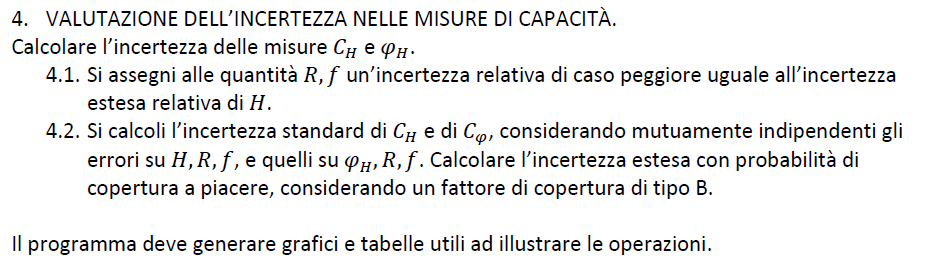

## Calcolo l'incertezza estesa relativa di C_H

% Calcolo incertezza relativa estesa sulla misura di risposta in ampiezza
Ur_H = U_H/abs(H)

Ur_H =       0.01008



% Imposto l'incertazza relativa di caso peggiore
Ur_100_R = Ur_H;
Ur_100_f = Ur_H;

% Calcolo simbolico dei coefficienti di sensibilità relativi per la mkisura
% di capacità in ampiezza

syms C_H_sym R_sym f_sym H_sym C_phi_sym phi_sym x1_sym x2_sym CrH_sym CrPhi_sym as real

% definisco la funzione di calcolo della capacità nota la risposta in
% ampiezza
C_H_sym = sqrt(1 - H_sym^2)/H_sym*(1/(2*pi*R_sym*f_sym))

$$C\_H\_sym = \frac{\sqrt{1-{H_{\mathrm{sym}}}^{2}}}{2\,H_{\mathrm{sym}}\,R_{\mathrm{sym}}\,f_{\mathrm{sym}}\,\pi }$$


% definisco il vettore degli ingressi per la misura di capacità
x1_sym = [H_sym R_sym f_sym]'

$$x1\_sym = \left(\begin{array}{c} H_{\mathrm{sym}}\\ R_{\mathrm{sym}}\\ f_{\mathrm{sym}} \end{array}\right)$$


% calcolo coefficienti di sensibiltà relativi
CrH_sym = simplify(jacobian(log(C_H_sym), x1_sym).*x1_sym')

$$CrH\_sym = \left(\begin{array}{ccc} \frac{1}{{H_{\mathrm{sym}}}^{2}-1} & -1 & -1 \end{array}\right)$$


% stima dell'incertezza standard, supponendo in ingresso distribuzione
% uniforme poiché note le incertezze di caso peggiore relative
ur_f = Ur_100_f/sqrt(3)

ur_f =     0.0058199


ur_R = Ur_100_R/sqrt(3)

ur_R =     0.0058199



% calcolo pratico, sostituendo ai valori simbolici i valori noti, calcolati
% precedentemente
CrH = [(1/(H^2 - 1)) -1 -1]

CrH =       -40.421           -1           -1



ur_C_H = [ur_H ur_R ur_f]

ur_C_H =     0.0051369    0.0058199    0.0058199



% stima matrice covarianza relativa in ingresso per la misura della
% capacità con risposta in ampiezza
sigmar_C_H_input = diag(ur_C_H.^2)

sigmar_C_H_input =    2.6388e-05            0            0
            0   3.3871e-05            0
            0            0   3.3871e-05



% stima matrice covarianza relativa in uscita
sigmar_C_H_output = CrH*sigmar_C_H_input*CrH'

sigmar_C_H_output =      0.043181



% stima incertezza standard in uscita
ur_CH = sqrt(diag(sigmar_C_H_output))

ur_CH =        0.2078



% stima incertezza assoluta della misura di capacità in uscita, noti
% l'incertezza relativa in uscita ed il modulo della capacità
u_CH = ur_CH * abs(C_H)

u_CH =     2.237e-09


## Calcolo dell'incertezza relativa di C_phi

% calcolo simbolico coefficienti relativi della misura di capacità nota la
% risposta di fase
C_phi_sym = tan(-phi_sym)*(1/(2*pi*R_sym*f_sym))

$$C\_phi\_sym = -\frac{\tan\left(\varphi_{\mathrm{sym}}\right)}{2\,R_{\mathrm{sym}}\,f_{\mathrm{sym}}\,\pi }$$


x2_sym = [phi_sym R_sym f_sym]'

$$x2\_sym = \left(\begin{array}{c} \varphi_{\mathrm{sym}}\\ R_{\mathrm{sym}}\\ f_{\mathrm{sym}} \end{array}\right)$$


CrPhi_sym = simplify(jacobian(log(C_phi_sym), x2_sym).*x2_sym')

$$CrPhi\_sym = \left(\begin{array}{ccc} \frac{2\,\varphi_{\mathrm{sym}}}{\sin\left(2\,\varphi_{\mathrm{sym}}\right)} & -1 & -1 \end{array}\right)$$


%double(subs(CrPhi_sym,x2_sym,[phi R fx]))

% sostituisco le relazioni ottenute col calcolo simbolico usando le
% variabili calcolate prima
CrPhi = [(2*phi/sin(2*phi)) -1 -1]

CrPhi =        1.0159           -1           -1



ur_phi = u_phi / abs(phi)

ur_phi =      0.033499



ur_C_Phi = [ur_phi ur_R ur_f]

ur_C_Phi =      0.033499    0.0058199    0.0058199



% stima matrice covarianza relativa in ingresso
sigmar_C_Phi_input = diag(ur_C_Phi.^2)

sigmar_C_Phi_input =     0.0011222            0            0
            0   3.3871e-05            0
            0            0   3.3871e-05



% stima matrice covarianza relativa in uscita
sigmar_C_Phi_output = CrPhi*sigmar_C_Phi_input*CrPhi'

sigmar_C_Phi_output =     0.0012259



ur_CPhi = sqrt(diag(sigmar_C_Phi_output))

ur_CPhi =      0.035013



% calcolo incertezza relativa in uscita note la misura di capacità e
% l'incertezza relativa sulla misura ottenuta dalla risposta di fase
u_CPhi = ur_CPhi * abs(C_phi)

u_CPhi =    5.2289e-10


## Calcolo incertezze estese con cp = 90%

% stima incertezze estese con valutazioe di tipo B (dunque usando norminv)
k = norminv((1+0.9)/2)

k =        1.6449



U_90_C_H = k*u_CH

U_90_C_H =    3.6795e-09



U_90_C_Phi = k*u_CPhi

U_90_C_Phi =    8.6008e-10
